format long;
A=128;
N=512;
pat=[1 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 1];
K=A+length(pat)-1;
nL=18;
data=load("reliability_sequence.mat");
req=data.reliability_full(data.reliability_full<=N);
g=[1 0;1 1];
k=log2(N);
Gmat=1;
for i=1:k
    Gmat=kron(g,Gmat);
end
f = @(a,b) (1-2*(a<0)).*(1-2*(b<0)).*min(abs(a),abs(b));
g = @(a,b,c) b+(1-2*c).*a;
n = log2(N);
EbNodB = linspace(-1.5,1.5,12);
Rate = (A*1.0)/N;
EbNo=10.^(EbNodB/10.0);
sigma = sqrt(1.0./(2*Rate*EbNo));
Q1=req(req<=N);
F = Q1(1:N-K);
BLER=zeros(1,length(EbNodB));
tic;
Nblocks = 1000;
for i=1:length(sigma)
    x=0;
%    Q1=fliplr(getReliabilitySequence(1/(sigma(i)^2),N));
 %+   F=Q1(1:N-K);
    for blk = 1:Nblocks
        msgn = rand(1,A)<=0.5;
        msgn_shifted=[msgn zeros(1, length(pat)-1)];
        [quot,rem] = gfdeconv(fliplr(msgn_shifted),fliplr(pat));
        rem=fliplr(rem);
        crc=[zeros(1,(length(pat)-1)-length(rem)) rem];
        msg=[msgn crc];
        u = zeros(1,N);
        u(Q1(N-K+1:end)) = msg;
        cword = mod(u*Gmat,2);
        s = 1-2*cword;
        r=s+sigma(i)*randn(1,N);
        rq=r;
        L=zeros(n+1,N);
        ucap=zeros(n+1,N);
        ns=zeros(1,2*N-1);
        L(1,:)=rq;
        LLR = zeros(nL,n+1,N); 
        ucap = zeros(nL,n+1,N); 
        PML = Inf*ones(nL,1);
        PML(1) = 0;
        ns = zeros(1,2*N-1);
            
        LLR(:,1,:) = repmat(rq,nL,1,1); 
        DML = zeros(nL,N);
        PMLL = zeros(nL,N);
        
        node = 0; depth = 0; 
        done = 0; 
        while (done == 0) 
            if depth == n
                DM = squeeze(LLR(:,n+1,node+1)); 
                DML(:,node+1) = DM;
                PMLL(:,node+1) = PML;
                if any(F==(node+1)) 
                    ucap(:,n+1,node+1) = 0;
                    PML = PML + abs(DM).*(DM < 0); 
                else
                    dec = DM < 0; 
                    PM2 = [PML; PML+abs(DM)];
                    [PML, pos] = mink(PM2,nL);
                    pos1 = pos > nL; 
                    pos(pos1) = pos(pos1) - nL; 
                    dec = dec(pos); 
                    dec(pos1) = 1 - dec(pos1);
                    LLR = LLR(pos,:,:); 
                    ucap = ucap(pos,:,:);
                    ucap(:,n+1,node+1) = dec;
                end
                if node == (N-1)
                    done = 1;
                else
                    node = floor(node/2); depth = depth - 1;
                end
            else
                npos = (2^depth-1) + node + 1;
                if ns(npos) == 0 
                    temp = 2^(n-depth);
                    Ln = squeeze(LLR(:,depth+1,temp*node+1:temp*(node+1))); 
                    a = Ln(:,1:temp/2); b = Ln(:,temp/2+1:end); 
                    node = node *2; depth = depth + 1; 
                    temp = temp / 2; 
                    LLR(:,depth+1,temp*node+1:temp*(node+1)) = f(a,b);
                    ns(npos) = 1;
                else
                    if ns(npos) == 1 
                        temp = 2^(n-depth);
                        Ln = squeeze(LLR(:,depth+1,temp*node+1:temp*(node+1)));
                        a = Ln(:,1:temp/2); b = Ln(:,temp/2+1:end);
                        lnode = 2*node; ldepth = depth + 1; 
                        ltemp = temp/2;
                        ucapn = squeeze(ucap(:,ldepth+1,ltemp*lnode+1:ltemp*(lnode+1)));
                        node = node *2 + 1; depth = depth + 1; 
                        temp = temp / 2; 
                        LLR(:,depth+1,temp*node+1:temp*(node+1)) = g(a,b,ucapn); 
                        ns(npos) = 2;
                    else 
                        temp = 2^(n-depth);
                        lnode = 2*node; rnode = 2*node + 1; cdepth = depth + 1; 
                        ctemp = temp/2;
                        ucapl = squeeze(ucap(:,cdepth+1,ctemp*lnode+1:ctemp*(lnode+1))); 
                        ucapr = squeeze(ucap(:,cdepth+1,ctemp*rnode+1:ctemp*(rnode+1))); 
                        ucap(:,depth+1,temp*node+1:temp*(node+1)) = [mod(ucapl+ucapr,2) ucapr]; 
                        node = floor(node/2); depth = depth - 1;
                    end
                end
            end
        end
        msg_capl = squeeze(ucap(:,n+1,Q1(N-K+1:end))); %get candidate messages
        cout = []; 
        for c1 = 1:nL
            [q1,r1] = gfdeconv(fliplr(msg_capl(c1,:)),fliplr(pat));
            if all(r1==0)
                cout = [cout c1];
            end
        end
        DMtest=DM(cout(:));
        msg_capltest=msg_capl(cout(:),:);
        if(isempty(cout))
            [~,indx]=min(DM);
            msg_cap=msg_capl(indx,1:A);
        elseif(length(cout)>1)
            [~,indx]=min(DMtest);
            msg_cap=msg_capltest(indx,1:A);
        else
            msg_cap=msg_capl(cout(1),1:A);
        end
        Nerrs = sum(msgn ~= msg_cap);
        if Nerrs > 0
            x=x+1;
        end
    end	
    BLER(i)=(1.0*x)/Nblocks;
end
toc;

Elapsed time is 1745.197013 seconds.


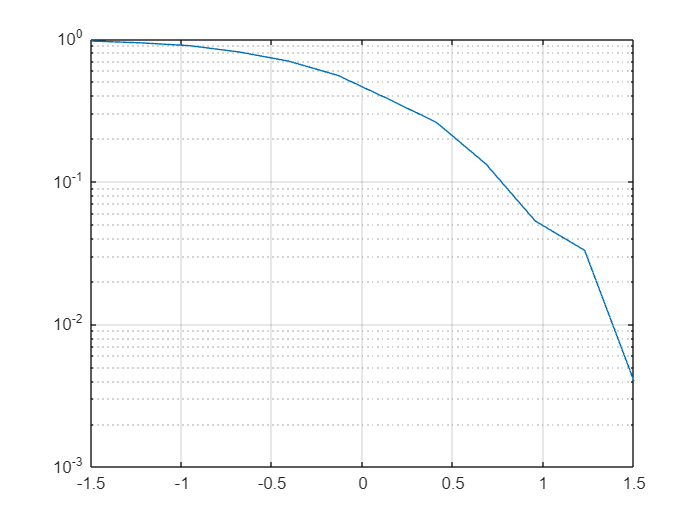


figure;
semilogy(EbNodB,BLER);
ylim([1e-03 1e-00]);
grid on;
hold on;